# 11 Classical Time Series Forecasting Methods in MATLAB

Kevin Chng

The blooming of machine learning implementation, it has raised interest from different industries to adopt it for classification and forecasting on time series problem.

Before exploring machine learning methods for time series, it is good idea to ensure you have tried classifical and statistical time series forecasting methods, those methods are still performing well on a wide range of problems, provided the data is suitably prepared and the method is well configured.

In this article, it listed some classical time series techniques available in MATLAB, you may try them on your forecasting problem prior to exploring to machine learning methods. 

It give you hints on each method to get started with a working code example and where to look to get more information on the method.

Overview:

This article demostrates 11 different classical time series forecasting methods, they are

My other revelevant articles:

1) VAR Model To Predict Malaysia/U.S. Foreign Exchange Rate

[https://www.mathworks.com/matlabcentral/fileexchange/71767-var-model-to-predict-malaysia-u-s-foreign-exchange-rate](https://www.mathworks.com/matlabcentral/fileexchange/71767-var-model-to-predict-malaysia-u-s-foreign-exchange-rate)

2) Stock Prediction Using ARIMA

[https://www.mathworks.com/matlabcentral/fileexchange/68576-stock-prediction-using-arima](https://www.mathworks.com/matlabcentral/fileexchange/68576-stock-prediction-using-arima)

3) GDP Prediction Using ARIMA and NAR Neural Network

[https://www.mathworks.com/matlabcentral/fileexchange/68389-gdp-prediction-using-arima-and-nar-neural-network](https://www.mathworks.com/matlabcentral/fileexchange/68389-gdp-prediction-using-arima-and-nar-neural-network)

## 1) Autoregression (AR)

The autoregression (AR) method models the next step in the sequene as a linear function of the observations at prior time steps.

The notation for the model involves specifying the order of the model p as a parameter to the AR function. For example,????

The method is suitable for univariate time series without trend and seasonal components

Documentation 

Model Mathematics : [https://www.mathworks.com/help/econ/autoregressive-model.html#responsive_offcanvas](https://www.mathworks.com/help/econ/autoregressive-model.html#responsive_offcanvas)

Function : [https://www.mathworks.com/help/econ/specify-ar-models.html](https://www.mathworks.com/help/econ/specify-ar-models.html)

% Time series z9 with noise
load iddata9 z9
data = get(z9).OutputData{1};
% Estimate a fourth-order AR model
sys = arima(15,0,0);
Md1 = estimate(sys,get(z9).OutputData{1});

 
    ARIMA(15,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0038176      0.028818        -0.13247        0.89461
    AR{1}           0.3893      0.044689          8.7114     3.0023e-18
    AR{2}          0.32699      0.050645          6.4565     1.0716e-10
    AR{3}          0.25647      0.051755          4.9555     7.2162e-07
    AR{4}         0.028275      0.052512         0.53844        0.59028
    AR{5}        0.0015907      0.053853        0.029538        0.97644
    AR{6}        -0.023294      0.050814        -0.45842        0.64665
    AR{7}          -0.1204

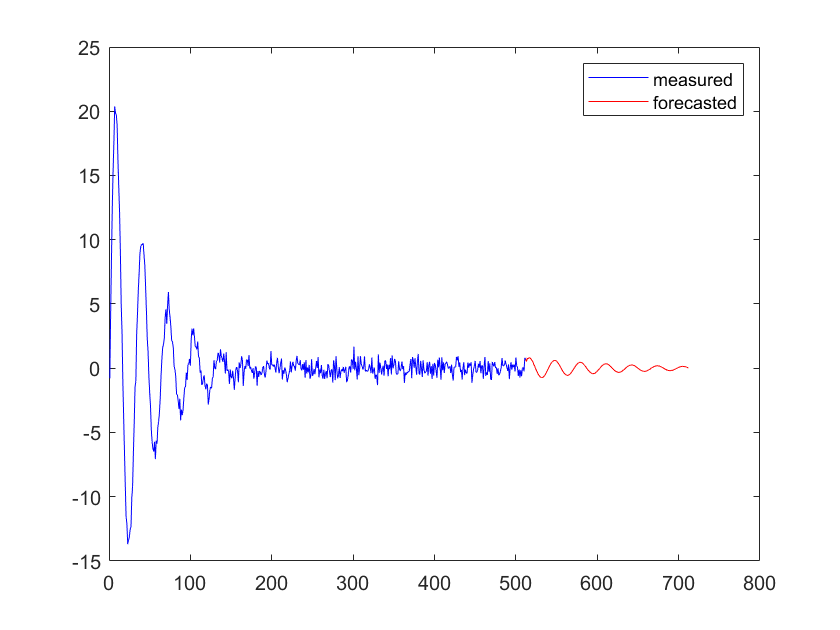

yf = forecast(Md1,200,'Y0',get(z9).OutputData{1});
% forecast
yf = forecast(Md1,200,'Y0',data); % Forecast 200 points ahead
plot(1:length(data),data,'b',length(data):length(data)+length(yf),[data(end);yf],'r'), legend('measured','forecasted')

## 2) Moving Average

The moving average (MA) method models the next step in the sequence as a linear function of the residual errors from a mean process at prior time steps. 

A moving average model is different from calculating the moving average of the time series.

The notation for the model involves specifying the order of the model q as a parameter to the MA function, eg. MA(q).. For example, MA(1) is the first-order moving average model.

The method is suitable for univariate time series without trend and seasonal components.

Documentation 

Model Mathematics : [https://www.mathworks.com/help/econ/moving-average-model.html](https://www.mathworks.com/help/econ/moving-average-model.html)

Function : [https://www.mathworks.com/help/econ/maq-models.html](https://www.mathworks.com/help/econ/maq-models.html)

Here, we can use ARIMA class to create MA model and setting a zeroth-order AR model

% Estimate a fourth-order AR model
sys = arima(0,0,40);
Md1 = estimate(sys,data);

 
    ARIMA(0,0,40) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant     -0.069703       0.22853        -0.30501         0.76036
    MA{1}          0.72259      0.027294          26.474     1.9312e-154
    MA{2}          0.88697      0.024236          36.598     3.1022e-293
    MA{3}                1      0.034522          28.967     1.7204e-184
    MA{4}                1      0.044834          22.304     3.3423e-110
    MA{5}                1      0.048848          20.472      3.8361e-93
    MA{6}          0.97945      0.084096          11.647      2.3823e-31
    MA{7}        

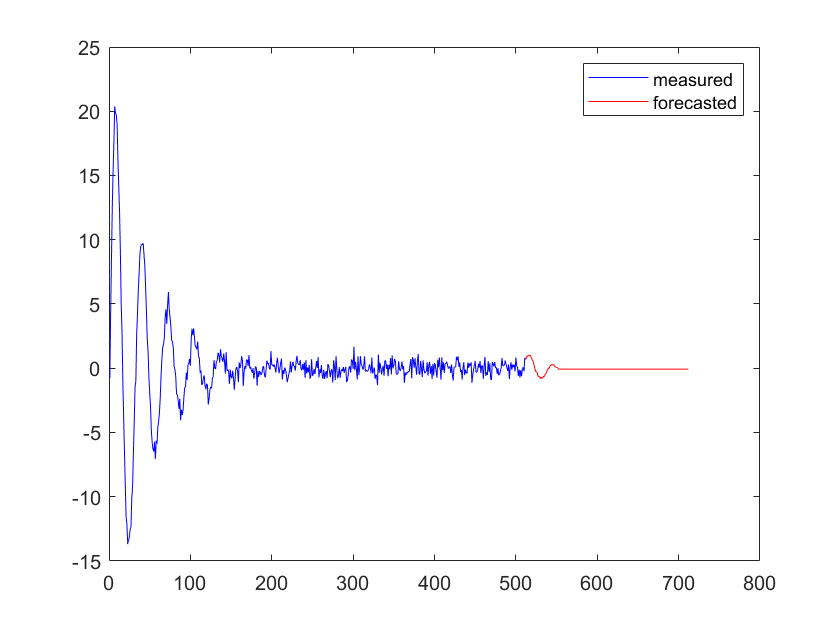

yf = forecast(Md1,200,'Y0',data);
plot(1:length(data),data,'b',length(data):length(data)+length(yf),[data(end);yf],'r'), legend('measured','forecasted')

## 3) Autoregressive Moving Average

The Autoregressive Integral Moving Average (ARIMA) method models the next step in the sequence as a linear function of the differenced observations and residual errors at prior time steps.

It combines both Autoregressive (AR) and Moving Average (MA) mdodels 

The notation for the model involves specifying the order for the AR(q) and MA(a) models as parameters to an ARMA function, e.g. ARMA(p,q). An ARIMA model can be used to develop AR or MA models.

The method is suitable for univariate time series without trend and seasonal components.

Documentation 

Model Mathematics : [https://www.mathworks.com/help/econ/arma-model.html](https://www.mathworks.com/help/econ/arma-model.html)

Function : [https://www.mathworks.com/help/econ/arma-models.html](https://www.mathworks.com/help/econ/arma-models.html)

sys = arima(15,0,40);
Md1 = estimate(sys,data);

 
    ARIMA(15,0,40) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant      0.014925       0.11078         0.13473        0.89283
    AR{1}         -0.17526       0.14225          -1.232        0.21794
    AR{2}          0.17414       0.20769         0.83845        0.40178
    AR{3}         0.078897       0.10422         0.75703        0.44903
    AR{4}         -0.11727        0.1565        -0.74933        0.45366
    AR{5}        -0.094811       0.17025        -0.55691        0.57759
    AR{6}          0.16071      0.091512          1.7562       0.079055
    AR{7}          0.2648

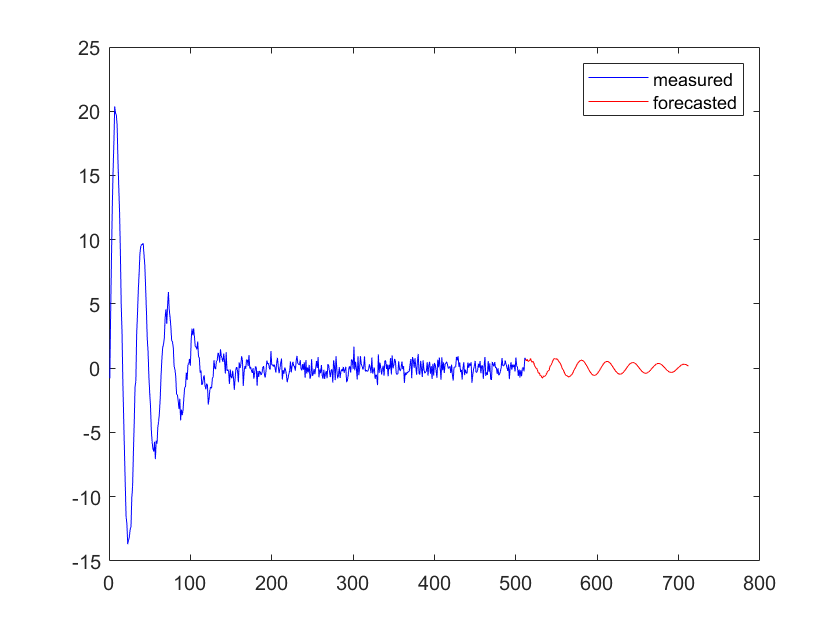

yf = forecast(Md1,200,'Y0',data);
plot(1:length(data),data,'b',length(data):length(data)+length(yf),[data(end);yf],'r'), legend('measured','forecasted')

## 4) Autoregressive Integrated Moving Average (ARIMA)

The Autoregressive Integrated Moving Average (ARIMA) method models the next step in the sequence as a linear function of the differenced observations and residual errors at the prior time steps.

It combines both Autoregression (AR) and Moving Average (MA) models as well as a differencing pre-processing step of the sequence to make the sequcne stationary, called integration.

The notation for the model involves specifiying the order for the AR(p), I(d), and MA(q) models as paramters to an ARIMA funciton. eg. ARIMA(p,d,q). An ARIMA can also be used to develop AR,MA, and ARMA models.

The method is suitable for univariate time series with trend and without seasonal components

Documentation 

Model Mathematics : [https://www.mathworks.com/help/econ/arima-model.html](https://www.mathworks.com/help/econ/arima-model.html)

Function : [https://www.mathworks.com/help/econ/arima.html](https://www.mathworks.com/help/econ/arima.html)

sys = arima(3,1,8);
Md1 = estimate(sys,data);

 
    ARIMA(3,1,8) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    2.5403e-05     1.6598e-05        1.5305           0.1259
    AR{1}           1.1781       0.041379         28.47      2.7429e-178
    AR{2}          0.45499       0.081163        5.6059       2.0722e-08
    AR{3}         -0.70055       0.041566       -16.854       9.8234e-64
    MA{1}               -2       0.062837       -31.829      2.6087e-222
    MA{2}          0.54223        0.14944        3.6285        0.0002851
    MA{3}                1         0.1481        6.7521       1.4576e-11
    MA{4}         

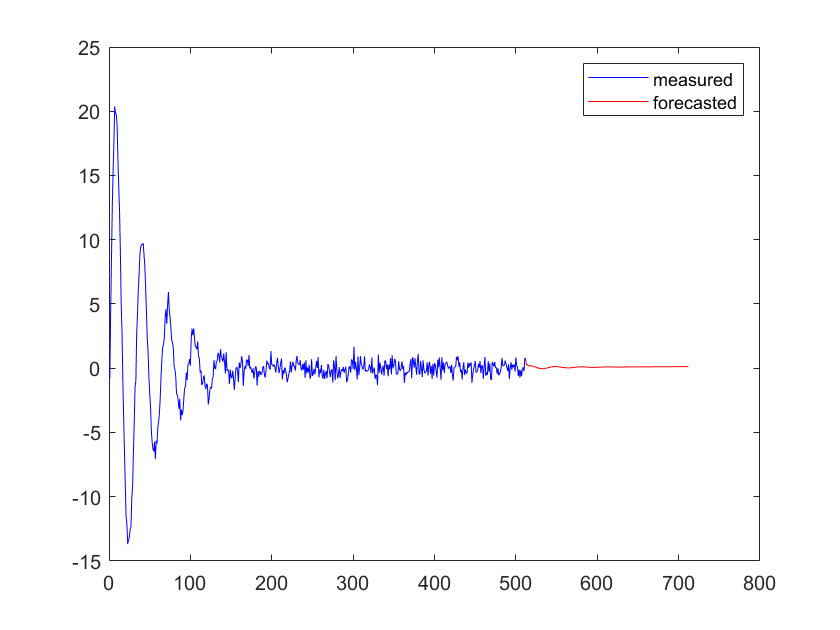

yf = forecast(Md1,200,'Y0',data);
plot(1:length(data),data,'b',length(data):length(data)+length(yf),[data(end);yf],'r'), legend('measured','forecasted')

## 5) Seasonal Autoregressive Integrated Moving-Average (SARIMA)

The Seasonal Autoregressive Integrated Moving Average (SARIMA) method models the next step in the sequcne as a linear function of the differenced observations, erros, differenced seasonal observations, and seasonal errors at prior time steps.

It combines the ARIMA model with the ability to perform the same autoregression, differencing, and moving average modeling at the seasonal level.

The notation for the model involves specifying the order for the AR(p), I(d), and MA(q) models as parameters to an ARIMA function and AR(P) , I(D), MA(Q) and m parameters at the seasonal level, e.g. SARIMA(p,d,q)(P,D,Q)m where "m" is the number of time steps in each season (the seasonal period). A SARIMA model can be used to develop AR, MA, ARMA, and ARIMA models.

The method is suitable for univariate time series with trend and/or seasonal components

Documentation 

Model Mathematics : [https://www.mathworks.com/help/econ/seasonal-arima-sarima-model.html](https://www.mathworks.com/help/econ/seasonal-arima-sarima-model.html)

Function : [https://www.mathworks.com/help/econ/arima.html?searchHighlight=sarima&s_tid=doc_srchtitle](https://www.mathworks.com/help/econ/arima.html?searchHighlight=sarima&s_tid=doc_srchtitle)

sys = arima('Constant',NaN,'ARLags',1:4,'D',0,'MALags',1:2,'SARLags',[12,24,36,48],'Seasonality',12,'SMALags',12,'Distribution','Gaussian');
Md1 = estimate(sys,data);

 
    ARIMA(4,0,2) Model Seasonally Integrated with Seasonal AR(48) and MA(12) (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0011171      0.0010688        1.0452         0.29592
    AR{1}          1.9822       0.045124        43.928               0
    AR{2}        -0.94448       0.098879       -9.5518      1.2746e-21
    AR{3}        -0.19326         0.0913       -2.1168        0.034281
    AR{4}          0.1256       0.038226        3.2858        0.001017
    SAR{12}            -1       0.058695       -17.037       4.339e-65
    SAR{24}      -0.70359       0.068206       -10.316      5.9915e-25

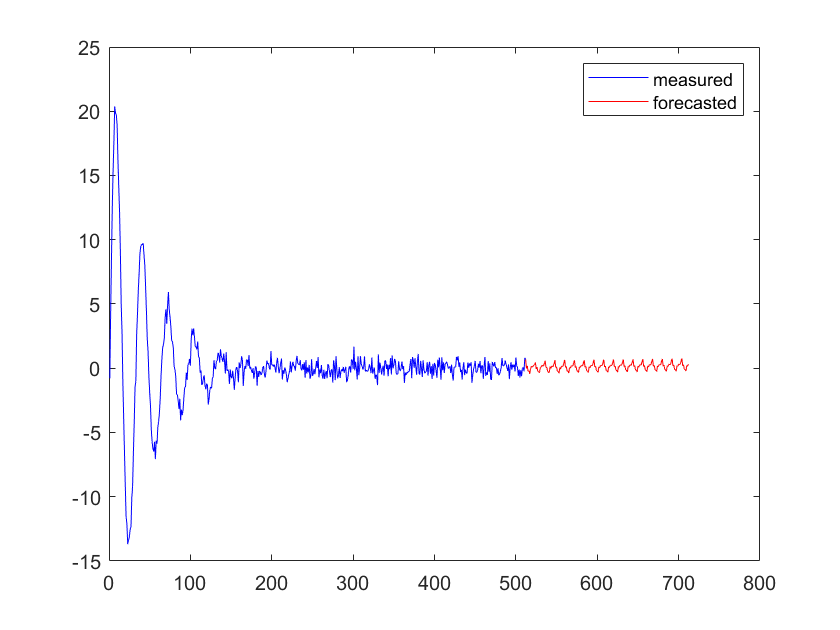

yf = forecast(Md1,200,'Y0',data);
plot(1:length(data),data,'b',length(data):length(data)+length(yf),[data(end);yf],'r'), legend('measured','forecasted')

## 6) Seasonal Autoregressive Integrated Moving Average with Exogenous Regressors (SARIMAX)

- It could be ARIMAX, ARMAX, ARX

The Seasonal Autoregressive Integrated Moving-Average with Exogenous Regressors (SARIMAX) is an extension of the SARIMA model that also includes the modeling of exogenous variables.

Exogenous variables are also called covariates and can be thought of as parallel input sequences that have observations at the same time steps as the orginal series. The primary series may be referred to as endogenous data to contrast it from the exogenous sequence(s). The observations for exogenous variables are included in the model directly at each time step and are not modeled in the same way as the primary endogenous sequence (e.g. as an AR, MA, etc. process).

The SARIMAX method can also be used to model the subsumed models with exogenous variables, such as ARX,MAX,ARMAX, and ARIMAX

The method is suitable for univariate time series with tend and/or seasonal components and exogenous variables.

Documentation 

Model Mathematics : [https://www.mathworks.com/help/econ/arima-model-including-exogenous-regressors.html](https://www.mathworks.com/help/econ/arima-model-including-exogenous-regressors.html)

Function : [https://www.mathworks.com/help/econ/arimax-model-specifications.html](https://www.mathworks.com/help/econ/arimax-model-specifications.html)

code here is ARIMAX

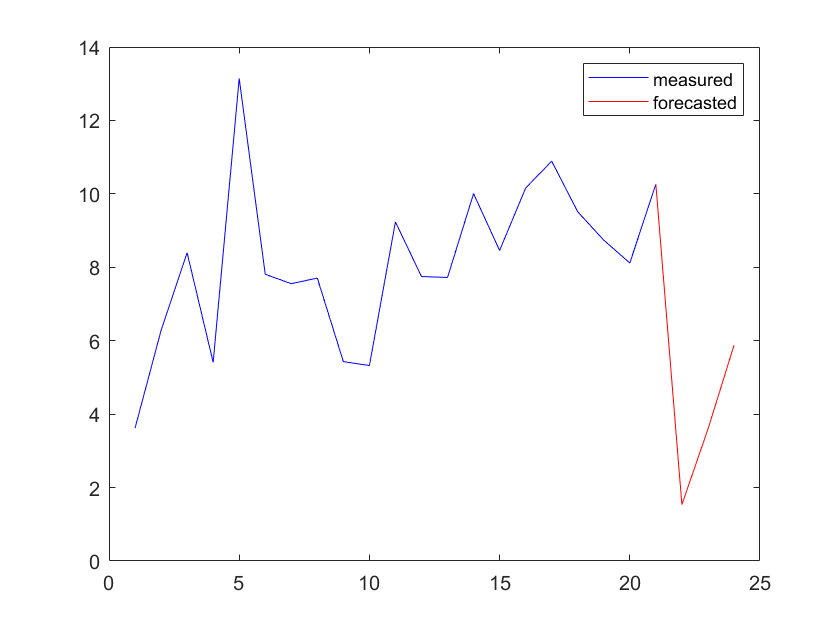

load Data_CreditDefaults

AGE = DataTable.AGE;
BBB = DataTable.BBB;
CPF = DataTable.CPF;
IGD = DataTable.IGD;
SPR = DataTable.SPR;

ARIMAX_AGE4 = arima('Constant',NaN,'ARLags',1:5,'D',2,'MALags',1:2,'Distribution','Gaussian');
validIndices = find(~any(isnan([AGE,BBB,CPF,IGD,SPR]),2));
preSampleNumber = ARIMAX_AGE4.P;
preSampleResponse = AGE(validIndices(1:preSampleNumber));
estimateResponse = AGE(validIndices(preSampleNumber+1:end));
ARIMAX_AGE4 = estimate(ARIMAX_AGE4,estimateResponse,'Y0',preSampleResponse,'X',[BBB,CPF,IGD,SPR],'Display','off');
yf = forecast(ARIMAX_AGE4,3);
plot(1:length(AGE),AGE,'b',length(AGE):length(AGE)+length(yf),[AGE(end);yf],'r'), legend('measured','forecasted')

## 8) Regression Model with ARIMA Error

Regression models with ARIMA time series errors contain two components which are a regression model and an error model. Typically, the research emphasis is on the regression model. But, in order to properly model the error structure. for detail, refers to [https://www.mathworks.com/help/econ/model-selection-for-regression-model-with-arima-errors.html](https://www.mathworks.com/help/econ/model-selection-for-regression-model-with-arima-errors.html)

The method is suitable for univariate time series with tend and/or seasonal components and exogenous variables.

Notes : [https://online.stat.psu.edu/stat510/book/export/html/669](https://online.stat.psu.edu/stat510/book/export/html/669)

function : [https://www.mathworks.com/help/econ/regarima-class.html](https://www.mathworks.com/help/econ/regarima-class.html)

X = randn(2,100);
X1 = X(:,1);
X2 = X(:,2);
RegARMA_X1 = regARIMA('Intercept',NaN,'ARLags',1:2,'MALags',1:3,'Distribution','Gaussian');
RegARMA_X1 = estimate(RegARMA_X1,X1,'X',X2);

 
    Regression with ARMA(2,3) Error Model (Gaussian Distribution):
 
                   Value      StandardError    TStatistic      PValue  
                 _________    _____________    __________    __________

    Intercept      0.23383       0.10382         2.2522        0.024307
    AR{1}          0.27936      0.099618         2.8043       0.0050422
    AR{2}         -0.76741      0.075907         -10.11      4.9929e-24
    MA{1}           -0.405       0.15387        -2.6321       0.0084853
    MA{2}          0.93233      0.082194         11.343      8.0338e-30
    MA{3}          0.12717       0.14382        0.88418          0.3766
    Beta(1)      -0.076544      0.078306        -0.9775         0.32832
    Variance 

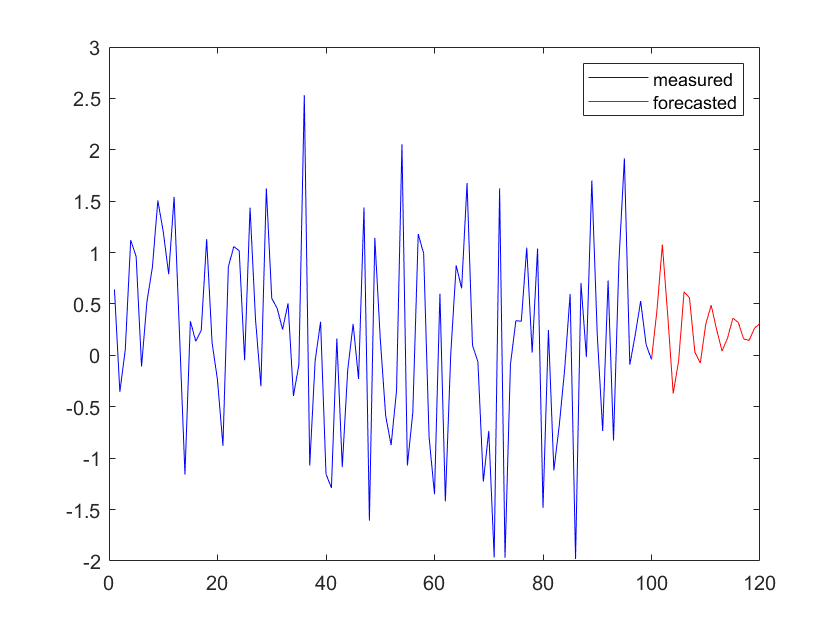

yf = forecast(RegARMA_X1,20,'Y0',X1);
plot(1:length(X1),X1,'b',length(X1):length(X1)+length(yf),[X1(end);yf],'r'), legend('measured','forecasted')

## 9) Vector Autoregression (VAR)

The Vector Autoregression (VAR) method to models the next step in each time series using an AR model. It is the generalization of AR to mulitple parallel time series, e.g. multivariate time series.

The notation for the model involves specificying the AR(p) model as paramters to a VAR function, e.g. VAR(p).

The method is suitable for multivariate time series without trend and seasonal components.

Documentation 

Model Mathematics : [https://www.mathworks.com/help/econ/introduction-to-vector-autoregressive-var-models.html](https://www.mathworks.com/help/econ/introduction-to-vector-autoregressive-var-models.html)

Function : [https://www.mathworks.com/help/econ/varm.html](https://www.mathworks.com/help/econ/varm.html)

Example : [https://www.mathworks.com/help/econ/var-model-case-study.html](https://www.mathworks.com/help/econ/var-model-case-study.html)

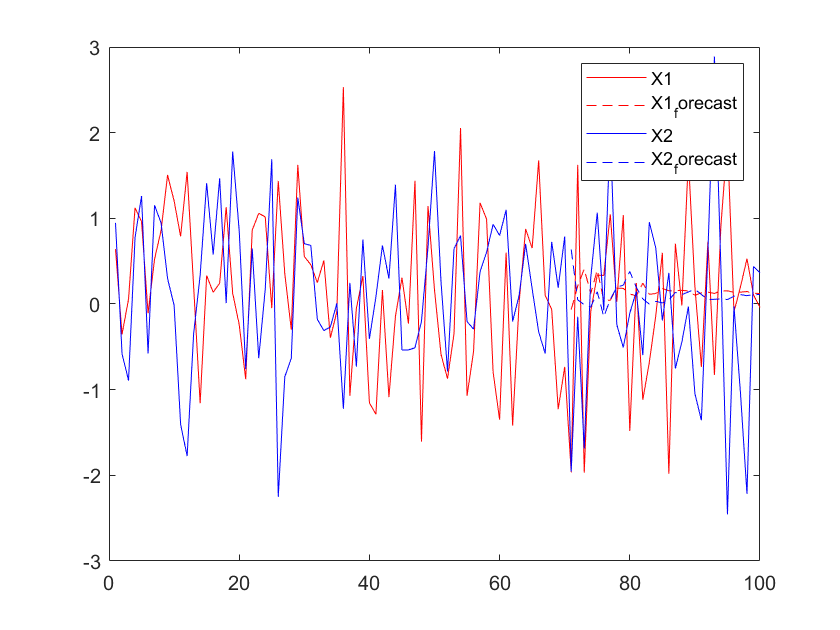

X = randn(2,100);
X = X';
numseries =2;
VAR2full = varm(numseries,10);
VAR2full.SeriesNames = {'X1','X2'};
idxPre = 1:19;
T = ceil(.7*size(X,1));
idxEst = 5:T;
idxF = (T+1):size(X,1);
fh = numel(idxF);
[EstMdl2,EstSE2,logL2,E2] = estimate(VAR2full,X,...
    'Y0',X(idxPre,:));
[FY2,FYCov2] = forecast(EstMdl2,fh,X(idxEst,:));
figure()
plot(1:100,X(:,1),'r')
hold on
plot(71:100,FY2(:,1),'r--')
plot(1:100,X(:,2),'b')
plot(71:100,FY2(:,2),'b--')
legend("X1","X1_forecast","X2","X2_forecast")
hold off

## 10) GARCH Model

GARCH models are conditionally heteroskedastic models with a constant unconditional variance. They have been widely used in financial and econometric modeling and analysis. These models are charaterized by their ability to capture volatility clustering and they are widely used to account for nonuniform variance in time-series data.

The method is suitable for univariate time series without trend and seasonal components.

Documentation 

Model Mathematics : [https://www.mathworks.com/help/econ/specify-garch-models-using-garch.html](https://www.mathworks.com/help/econ/specify-garch-models-using-garch.html)

Function : [https://www.mathworks.com/help/econ/garch.html](https://www.mathworks.com/help/econ/garch.html)

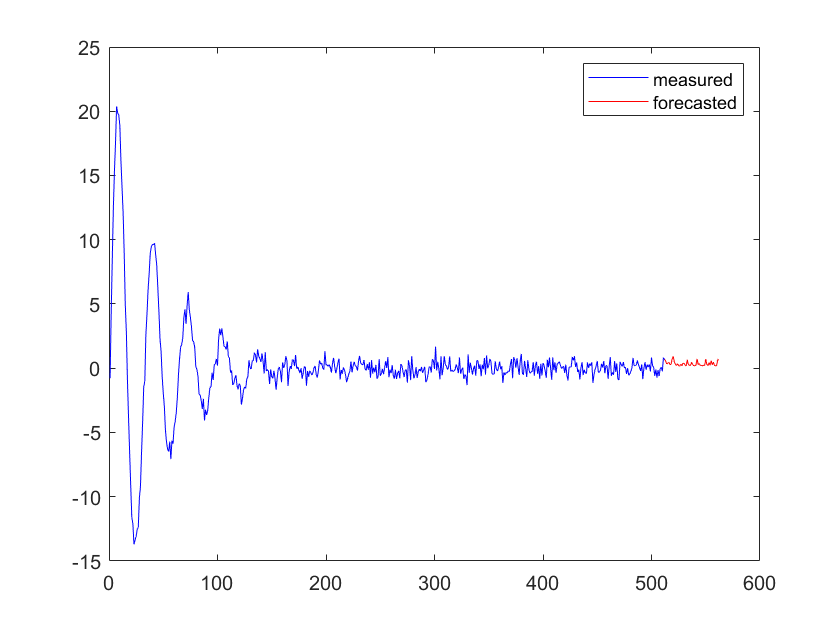

load iddata9 z9
data = get(z9).OutputData{1};
GARCH_X1 = garch('Offset',0,'GARCHLags',1:14,'ARCHLags',50,'Distribution','Gaussian');
GARCH_X1 = estimate(GARCH_X1,data,'Display','off');
yf = forecast(GARCH_X1,50,'Y0',data);
plot(1:length(data),data,'b',length(data):length(data)+length(yf),[data(end);yf],'r'), legend('measured','forecasted')

## 11) Glostan, Jagannathan and Runkle GARCH Model

A time series ARCH and GARCH model can explain the heterocedasticity of data, but they are not always able to fully capture the asymmertic property of hih frequency. GJR Garch model overcome GARCH weaknesses in capturing asymmerty good news and bad news taking into the leverage effect. GJR Garch models were used to estimate the value of VAR as the maximum loss that will be obtained during a certain period at a certain confidence level.

The method is suitable for univariate time series without trend and seasonal components.

Documentation 

Model Mathematics : [https://www.mathworks.com/help/econ/specify-gjr-models-using-gjr.html](https://www.mathworks.com/help/econ/specify-gjr-models-using-gjr.html)

Function : [https://www.mathworks.com/help/econ/gjr.html](https://www.mathworks.com/help/econ/gjr.html)

load iddata9 z9
data = get(z9).OutputData{1};
%% Glosten, Jagannathan, and Runkle Model
% Estimate a GJR Model of X1
GJR_X1 = gjr('Offset',0,'GARCHLags',1:3,'ARCHLags',1,'LeverageLags',1,'Distribution','Gaussian');
GJR_X1 = estimate(GJR_X1,data,'Display','off');
yf = forecast(GARCH_X1,50,'Y0',data);
plot(1:length(data),data,'b',length(data):length(data)+length(yf),[data(end);yf],'r'), legend('measured','forecasted')